# 3. (30%) A flat aluminum bar has constant thickness of 10 mm and a variable symmetric profile as shown in the figure below.

clc; clear; close all;

## (a) Construct the Lagrange interpolation functions.

syms x;

xe = [0 15 30 45 60 75 90];

N = sym(ones(7, 1));

for i = 1 : length(N)
    xj = (xe(xe ~= xe(i)));
    N(i, 1) = simplify(prod((x - xj) ./ (xe(i) - xj)));
end

thickness = 10; % mm
Ae = thickness * [8 10 9 12 12 10 5];

A(x) = Ae * N

$$A(x) = \begin{array}{l} 80\,\left(\frac{x}{15}-1\right)\,\left(\frac{x}{30}-1\right)\,\left(\frac{x}{45}-1\right)\,\left(\frac{x}{60}-1\right)\,\left(\frac{x}{75}-1\right)\,\left(\frac{x}{90}-1\right)+2\,x\,\left(\frac{x}{15}-3\right)\,\left(\frac{x}{15}-5\right)\,\left(\frac{x}{30}-1\right)\,\left(\frac{x}{30}-3\right)\,\left(\frac{x}{45}-\frac{1}{3}\right)-\frac{8\,x\,\left(\frac{x}{15}-2\right)\,\left(\frac{x}{15}-4\right)\,\left(\frac{x}{30}-\frac{1}{2}\right)\,\left(\frac{x}{30}-\frac{5}{2}\right)\,\left(\frac{x}{45}-2\right)}{3}+3\,x\,\left(\frac{x}{15}-1\right)\,\left(\frac{x}{15}-3\right)\,\left(\frac{x}{30}-2\right)\,\left(\frac{x}{45}-\frac{5}{3}\right)\,\left(\frac{x}{60}-\frac{3}{2}\right)-\frac{4\,x\,\left(\frac{x}{15}-4\right)\,\left(\frac{x}{15}-6\right)\,\sigma_{1}\,\left(\frac{x}{45}-\frac{2}{3}\right)\,\left(\frac{x}{60}-\frac{1}{4}\right)}{3}+\frac{5\,x\,\left(\frac{x}{15}-5\right)\,\left(\frac{x}{30}-2\right)\,\left(\frac{x}{45}-1\right)\,\left(\frac{x}{60}-\frac{1}{2}\right)\,\left(\frac{x}{75}-\frac{1}{5}\right)}{9}-\frac{20\,x\,\left(\frac{x}{15}-2\right)\,\sigma_{1}\,\left(\frac{x}{45}-\frac{4}{3}\right)\,\left(\frac{x}{60}-\frac{5}{4}\right)\,\left(\frac{x}{75}-\frac{6}{5}\right)}{3}\\ \mathrm{where}\\ \sigma_{1}=\frac{x}{30}-\frac{3}{2} \end{array}$$

## (b) Use the Lagrange interpolation functions given in (a) and determine the half-area function. Graph the interpolation with a MATLAB plot. The interpolation function should pass through all the seven data points. A sample MATLAB plot is given below.

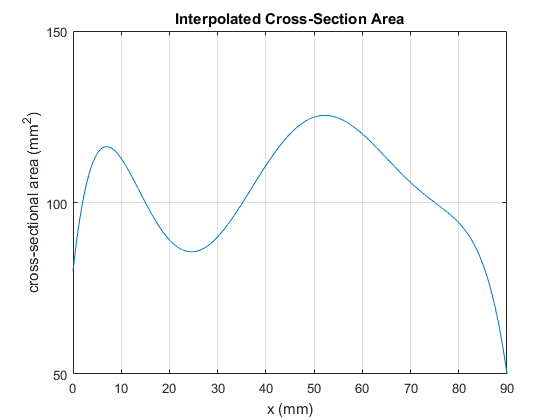

t = 0 : 0.01 : 90;

figure;
plot(t, A(t));
title('Interpolated Cross-Section Area');
xlabel('x (mm)');
ylabel('cross-sectional area (mm^2)');
yticks([50 100 150]);
axis([0 90 50 150]);
grid on;

## (c) Use the Lagrange interpolation functions given in (a) and determine the interpolation function for its profile. Graph the interpolation with a MATLAB plot. The interpolation function should pass through all the seven data points. A sample MATLAB plot is given below.

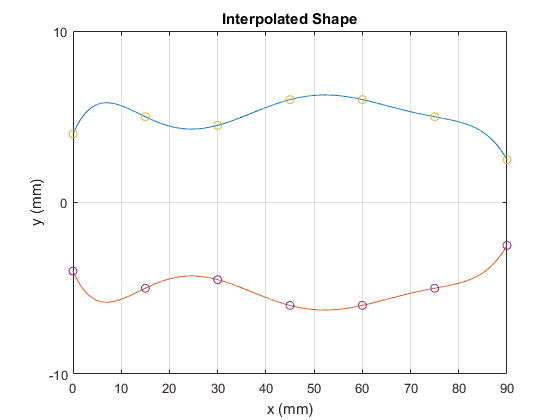

y = A(t) / thickness / 2;
ye = Ae / thickness / 2;

figure;
plot(t, y, t, - y, xe, ye, 'o', xe, - ye, 'o');
title('Interpolated Shape');
xlabel('x (mm)');
ylabel('y (mm)');
axis([0 90 -10 10]);
yticks([-10 0 10]);
grid on;